# Laboratorium 11

### Filtracja sygnałów, Filtry IIR

Janusz Pawlicki

## 1. Wstęp

Filtry FIR, dla przypomnienia, charakteryzują się m.in. stosunkowo prostą budową (algorytmem) i liniową fazą w zakresie częstotliwości przepuszczanych.

Drugą grupę stanowią filtry o nieskończonej odpowiedzi impulsowej, z angielska określane również skrótem IIR od angielskiej nazwy - Infinite Impulse Response. Filtry te są zasadniczo różne od filtrów FIR, ponieważ zawsze wymagają sprzężenia zwrotnego. O ile próbki sygnału wyjściowego filtru FIR zależą jedynie od przeszłych wartości sygnału wejściowego, to każda próbka wyjściowa filtru IIR zależy od poprzednich próbek sygnału wejściowego i poprzednich próbek sygnału wyjściowego. Stosowanie sprzężenia zwrotnego, czyli próbek wyjściowych podawanych z powrotem na wejście, jest zarówno korzystne, jak i niekorzystne.

Tak jak we wszystkich systemach ze sprzężeniem zwrotnym zmiany sygnału wejściowego filtru IIR mogą, w niektórych przypadkach, spowodować powstanie na wyjściu niestabilności i oscylacji o nieskończonym czasie trwania. Stąd też wzięła się nazwa "nieskończona odpowiedź impulsowa", czyli możliwość istnienia na wyjściu niezerowych próbek o nieskończonym czasie trwania w sytuacji, gdy na wejście filtru nie podawany jest żaden sygnał (lub próbki zerowe).

Jak się można więc domyślić już z tego opisu, struktura filtrów IIR nie będzie już taka prosta, jak filtrów FIR, a to oznacza, że są one trudniejsze do projektowania i analizy. Oprócz tego filtry IIR nie zapewniają, tak jak to było z filtrami FIR, liniowej fazy w zakresie przenoszenia.

Po cóż więc stosować i w ogóle zajmować się filtrami, które na pierwszy rzut oka mają same wady w stosunku do prostszych i łatwiejszych w projektowaniu filtrów FIR? Filtry IIR są po prostu bardziej efektywne, niż filtry FIR, czyli wymagają mniejszej liczby mnożeń dla wyliczenia pojedynczej próbki sygnału wyjściowego, przy zapewnieniu wymaganej charakterystyki częstotliwościowej. Ze sprzętowego punktu widzenia oznacza to, że filtry IIR mogą być bardzo szybkie, a więc mogą działać w czasie rzeczywistym, operując przy znacznie wyższych częstotliwościach próbkowania, niż filtry FIR.

Filtr IIR nie dość, że wymaga mniej, niż połowy mnożeń w stosunku do filtru FIR, to jeszcze ma mniejsze nierównomierności charakterystyki w paśmie przepustowym oraz większą stromość charakterystyki w paśmie przejściowym w porównaniu z filtrem o skończonej odpowiedzi impulsowej. (Rys. 1)

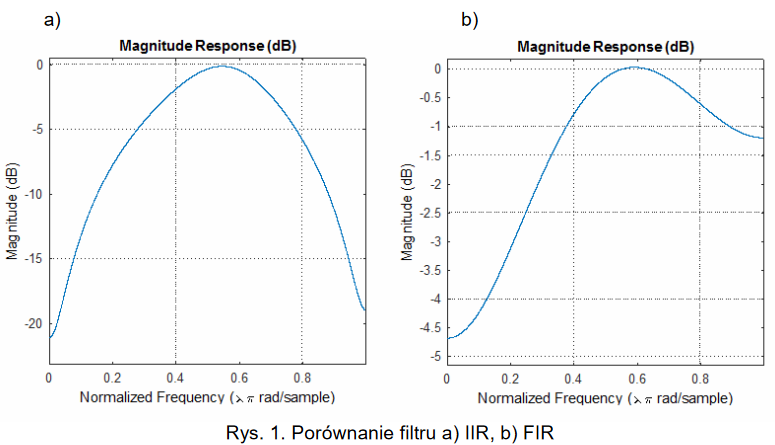

## 2. Przebieg laboratorium - zadania

### 2.1 Korzystając z Przykładu 4 zaprojektować filtr IIR:

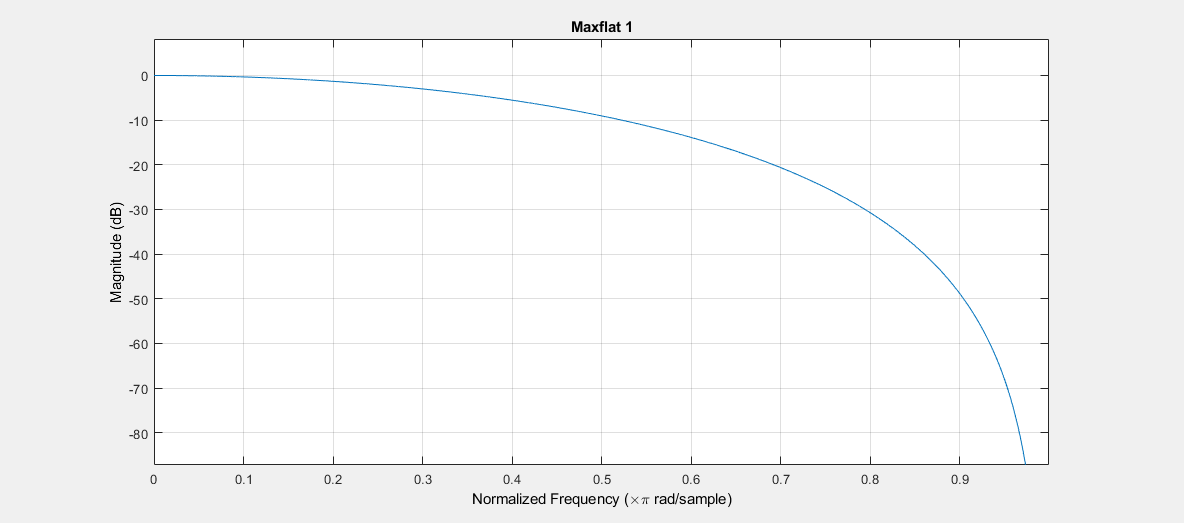

[b,a] = maxflat(4, 1, 0.3);
fvtool(b,a);
title('Maxflat 1');

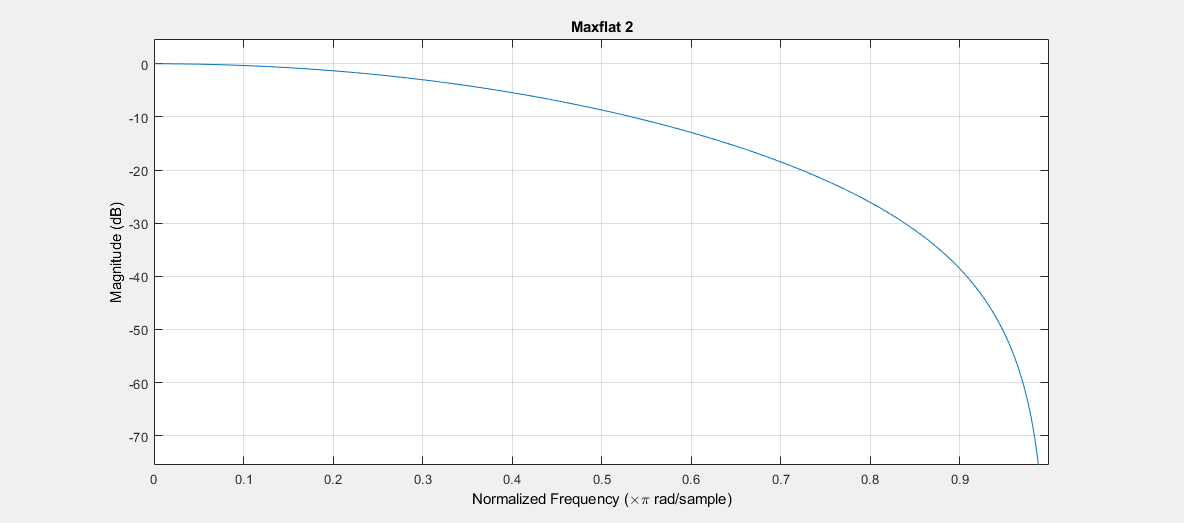


[b,a] = maxflat(4, 'sym', 0.3);
fvtool(b,a);
title('Maxflat 2');

### 2.2 Sprawdzić stabilność filtru o współczynnikach `b = [1 -0.5]; a = [1 -2]`

figure;
b = [1 -0.5]; a = [1 -2];
stab22 = isstable(b, a)

stab22 = logical
   0


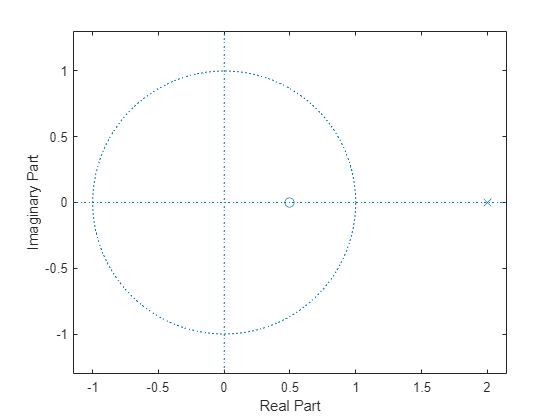

zplane(b, a);

Stab22 = 0, czyli filtr jest niestabilny.

### 2.3 Sprawdzić stabilność filtru o współczynnikach `b = [1 -0.1]; a = [-1 -0.1]`

figure;
b = [1 -0.1]; a = [-1 -0.1];
stab23 = isstable(b, a)

stab23 = logical
   1


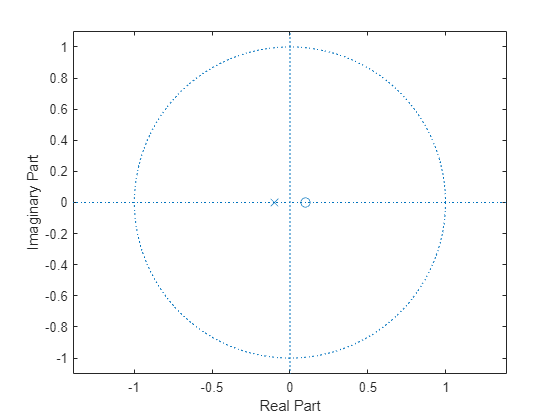

zplane(b, a);

Stab23 = 1, czyli filtr jest stabilny.

### 2.4 Sprawdzić stabilność filtru o współczynnikach `b` `=` `[0.9` `-0.8];` `a` `=` `[-0.9` `-0.8]`

figure;
b = [0.9 -0.8]; a = [0.9 -0.8];
stab24 = isstable(b, a)

stab24 = logical
   1


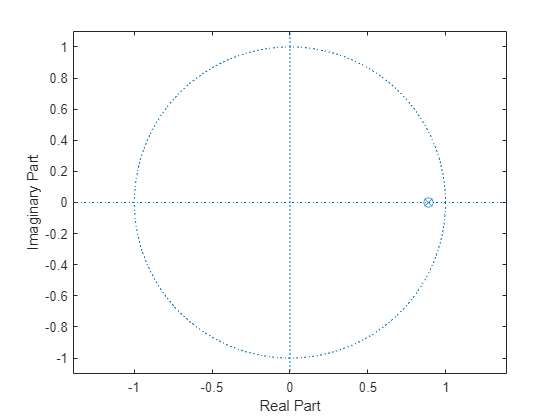

zplane(b, a);

Stab24 = 1, czyli filtr jest stabilny.

### 2.5 Sprawdzić stabilność filtru o współczynnikach `b = [0.9 -0.8 1 1]; a = [-0.9 -0.8 -1]`

figure;
b = [0.9 -0.8 1 1]; a = [-0.9 -0.8 -1];
stab25 = isstable(b, a)

stab25 = logical
   0


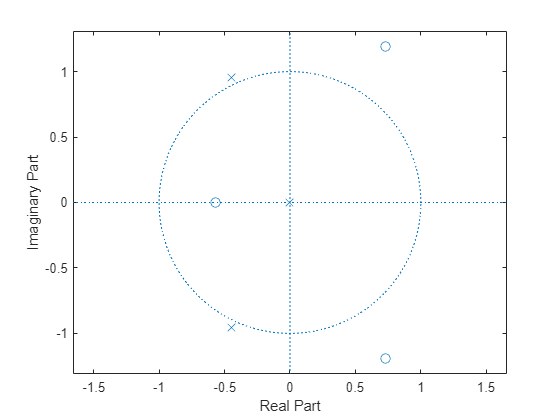

zplane(b, a);

Stab25 = 0, czyli filtr jest niestabilny.

### 2.6 Sprawdzić stabilność następującego filtru

figure;
m = [0 0 1 1 1 0 1 1 0 0];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1];
[b,a] = yulewalk(10,f,m);
Stab26 = isstable(b, a)

Stab26 = logical
   1


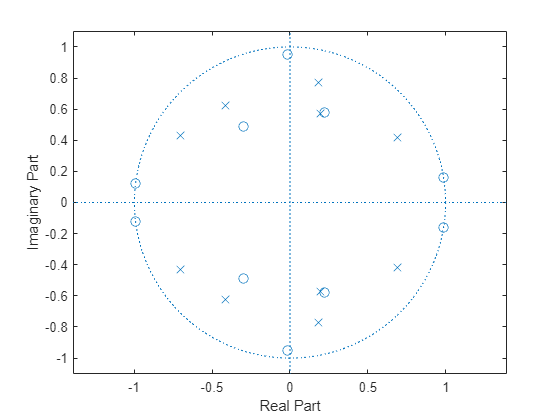

zplane(b, a);

Stab26 = 1, czyli filtr jest stabilny.

### 2.7 Przefiltrować sygnał `chirp` filtrem IIR `maxflat(4,1,0.3).` Narysować przebieg czasowy i częstotliwościowy przefiltrowanego sygnału.

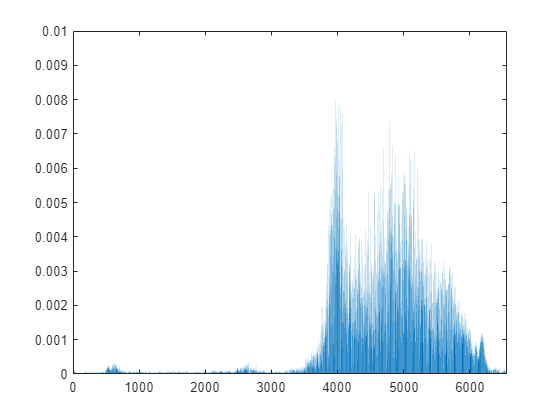

figure;
load chirp

t = (0:length(y)-1)/Fs;

xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

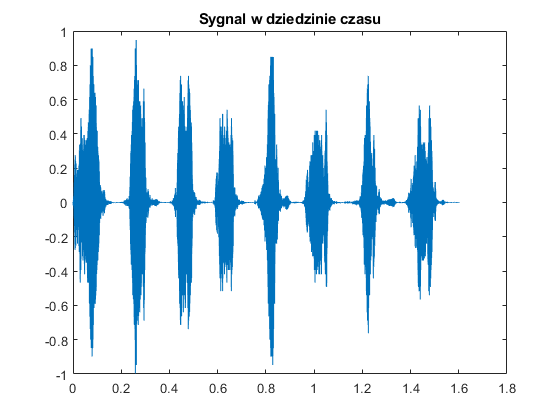

plot(t,y);
title('Sygnal w dziedzinie czasu');

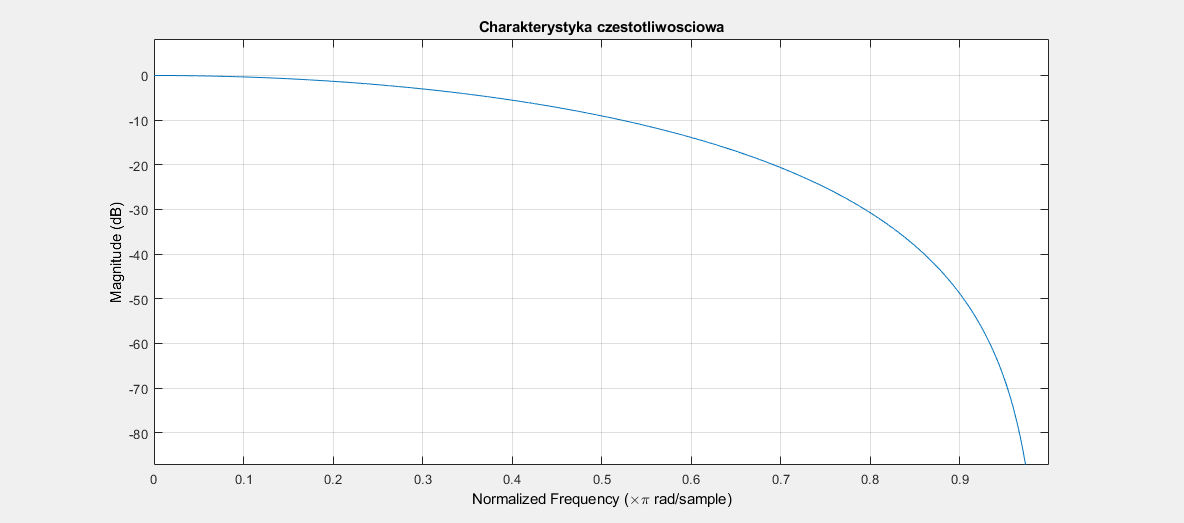


[b,a] = maxflat(4, 1, 0.3);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

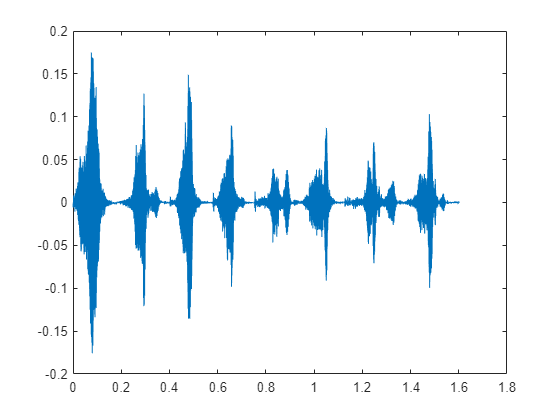

out = filter(b,a,y);

plot(t, out);

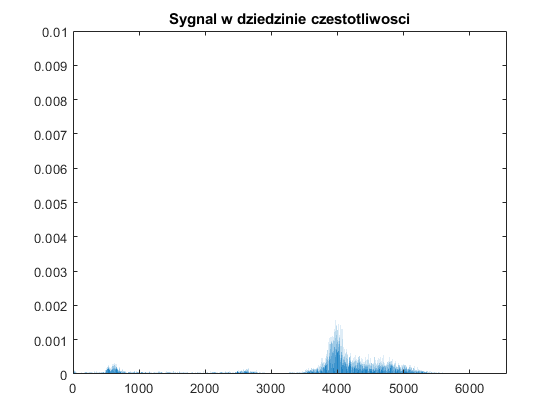

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

### 2.8 Przefiltrować sygnał `chirp `filtrem IIR

### Narysować przebieg czasowy i częstotliwościowy przefiltrowanego sygnału

figure;
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y);
title('Sygnal w dziedzinie czasu');

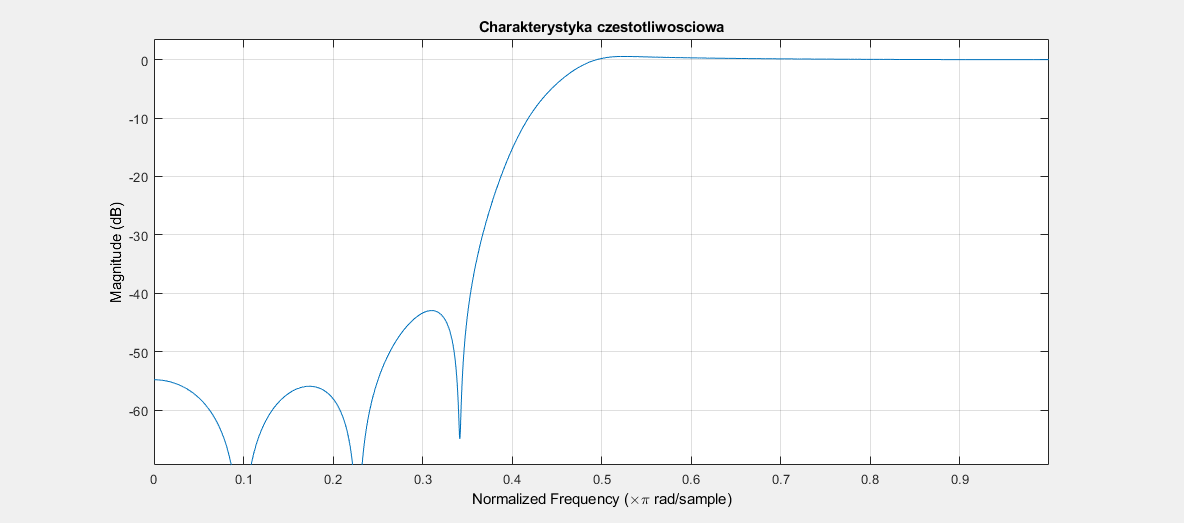


m = [0 0 0 0 0 1 1 1 1 1];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1];
[b,a] = yulewalk(10,f,m);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

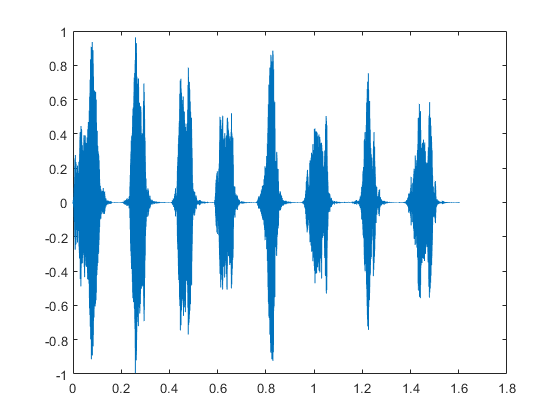


out = filter(b,a,y);
plot(t, out);

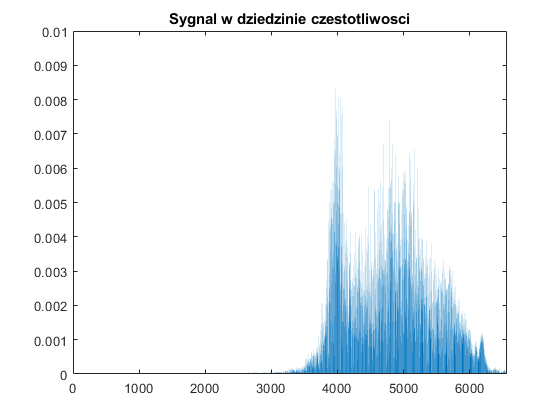

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

### 2.9 Przefiltrować sygnał `chirp `filtrem IIR. Uwaga filtr jest niestabilny. 

### `b = [0.9 -0.8 1 1]; a = [-0.9 -0.8 -1];`

### Narysować przebieg czasowy i częstotliwościowy przefiltrowanego sygnału. Narysować charakterystykę częstotliwościową filtru.

load chirp
figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y)
title('Sygnal w dziedzinie czasu');

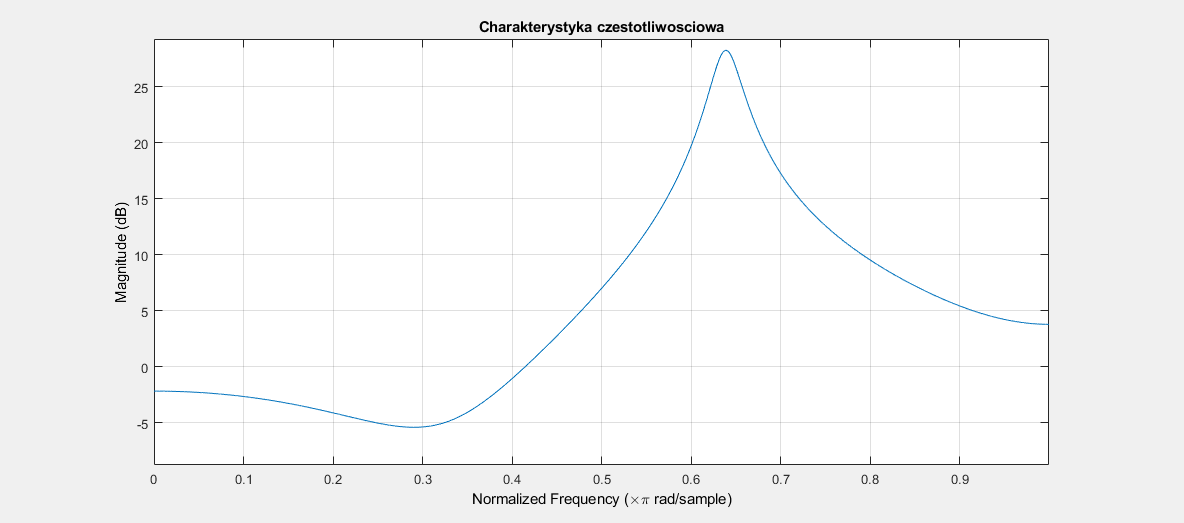


b = [0.9 -0.8 1 1];
a = [-0.9 -0.8 -1];
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

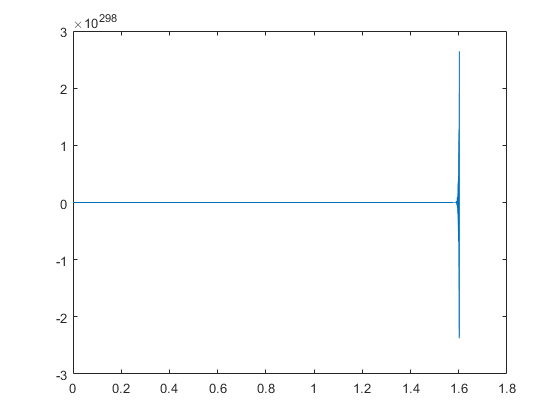


out = filter(b,a,y);
plot(t, out);

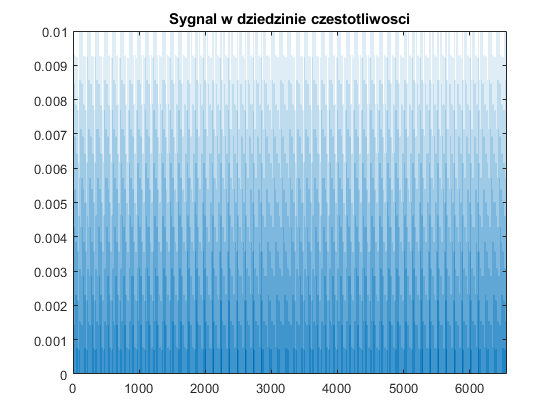

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

### 2.10  Przefiltrować sygnał `chirp` filtrem IIR, Butterwortha. Użyć funkcji `buttord` i `butter`. z parametrami

### Narysować przebieg częstotliwościowy przefiltrowanego sygnału. Narysować charakterystykę częstotliwościową filtru.

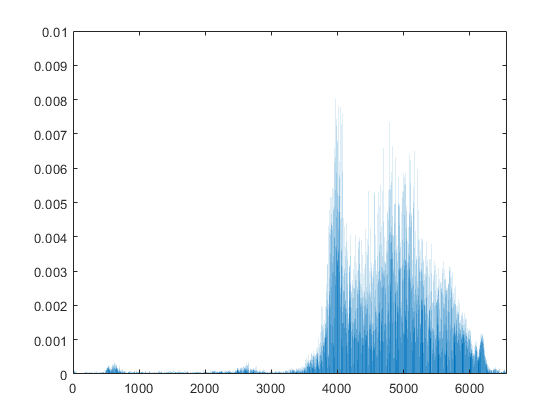

load chirp
figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y)
title('Sygnal w dziedzinie czasu');

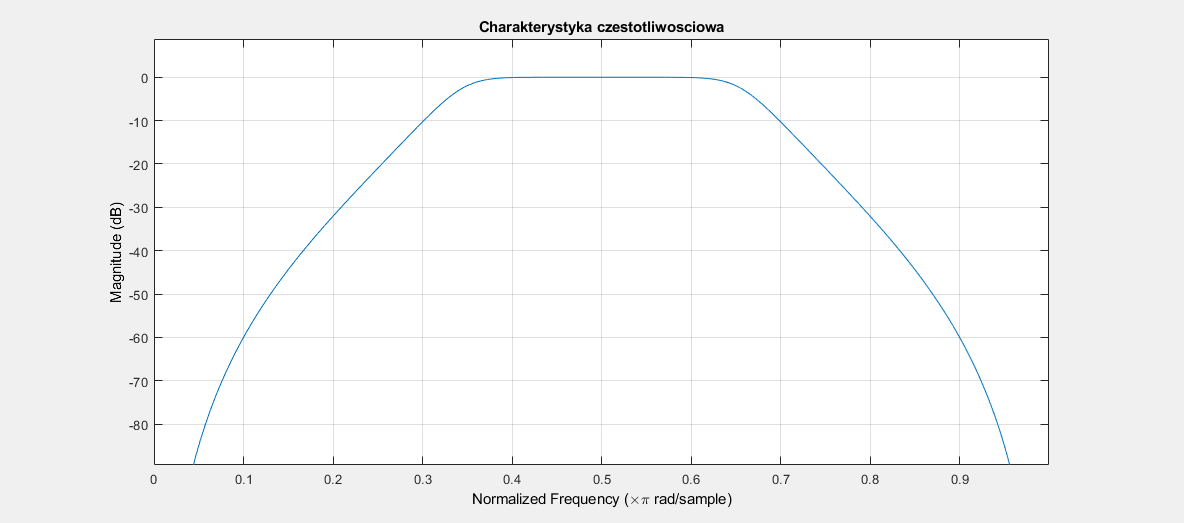


[n, Wn] = buttord([2000 3000]/5000, [500 4500]/5000,1,60);
[b,a] = butter(n,Wn);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

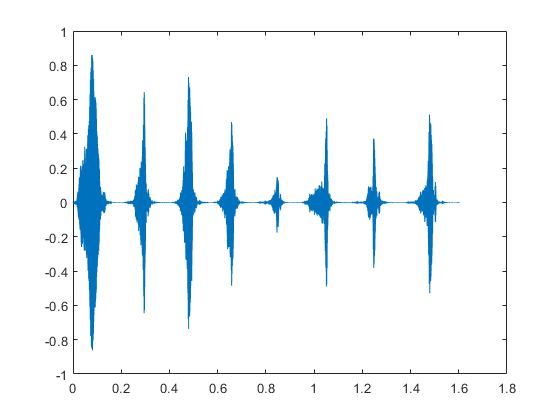


out = filter(b,a,y);
plot(t, out);

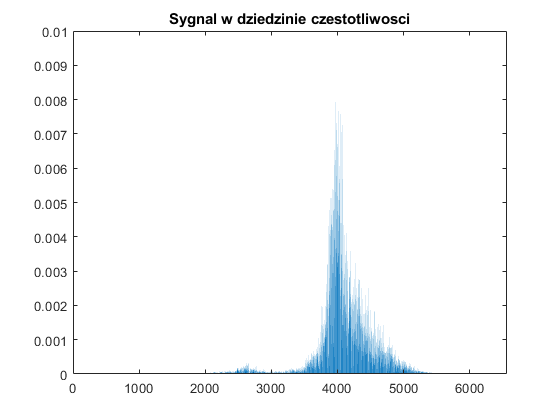

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

### 2.11  Przefiltrować sygnał `chirp` filtrem IIR, Butterwortha. Użyć funkcji `buttord` i `butter`. z parametrami

### Narysować przebieg częstotliwościowy przefiltrowanego sygnału. Narysować charakterystykę częstotliwościową filtru.

load chirp
figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y)
title('Sygnal w dziedzinie czasu');

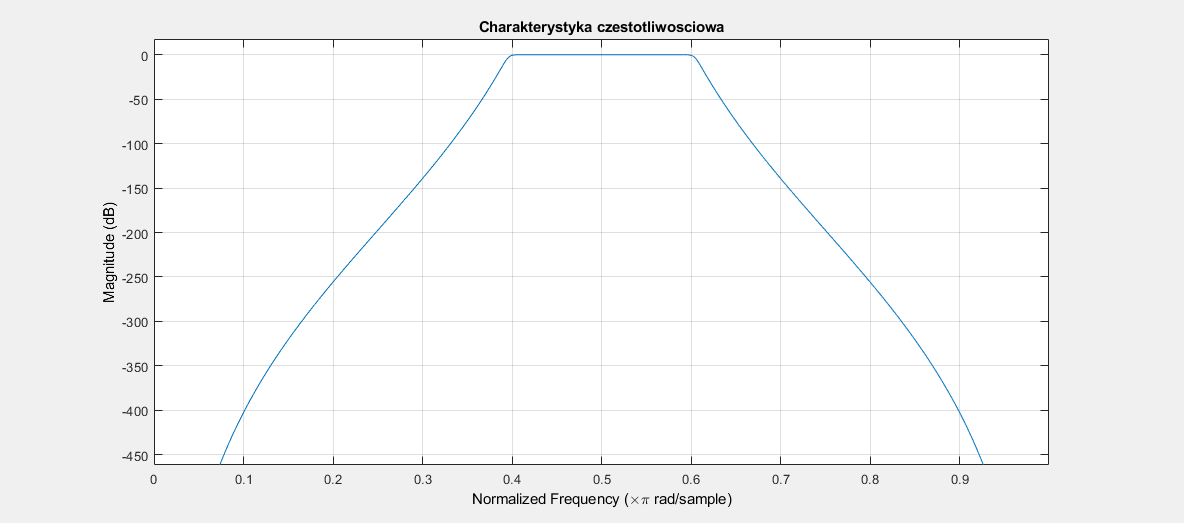


[n, Wn] = buttord([2000 3000]/5000, [1800 3200]/5000,1,60);
[b,a] = butter(n,Wn);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

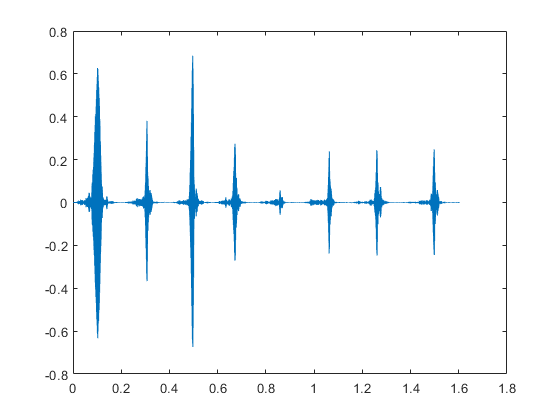


out = filter(b,a,y);
plot(t, out);

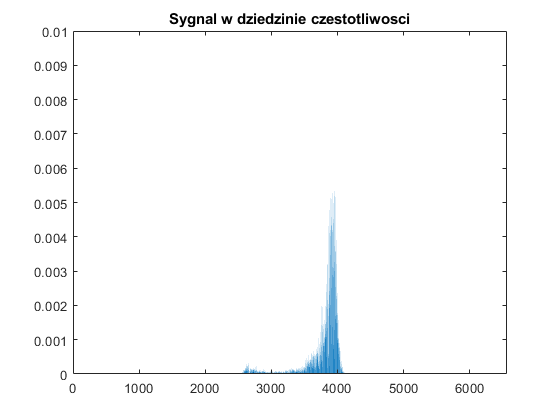

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

### 2.12  Przefiltrować sygnał `chirp` filtrem IIR, Butterwortha. Użyć funkcji `ellipord i` `ellip`. z parametrami

### Narysować przebieg częstotliwościowy przefiltrowanego sygnału. Narysować charakterystykę częstotliwościową filtru.

load chirp
figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y)
title('Sygnal w dziedzinie czasu');

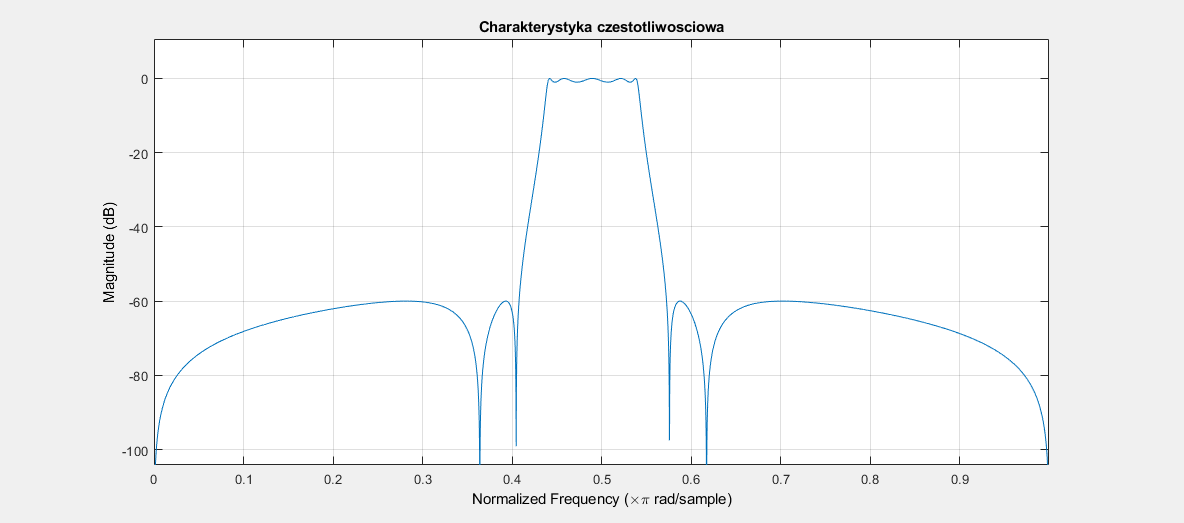


[n, Wn] = ellipord([2200 2700]/5000, [2000 2900]/5000,1,60);
[b,a] = ellip(n, 1, 60, Wn);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

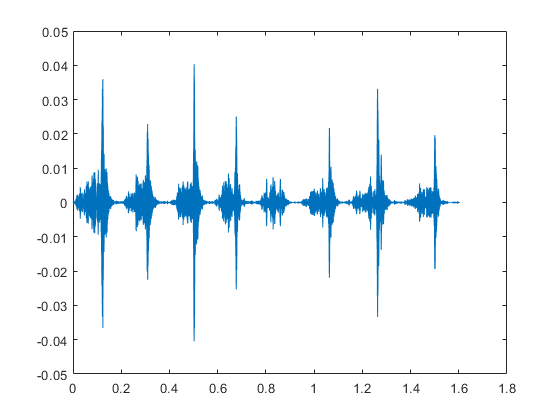


out = filter(b,a,y);
plot(t, out);

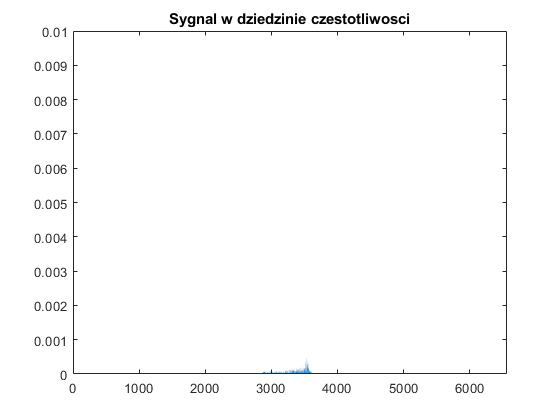

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

### 2.13  Przefiltrować sygnał `chirp` filtrem IIR, eliptycznym. Użyć funkcji `ellipord` `i ellip`. z parametrami

### Narysować przebieg częstotliwościowy przefiltrowanego sygnału. Narysować charakterystykę częstotliwościową filtru.

load chirp
figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y)
title('Sygnal w dziedzinie czasu');

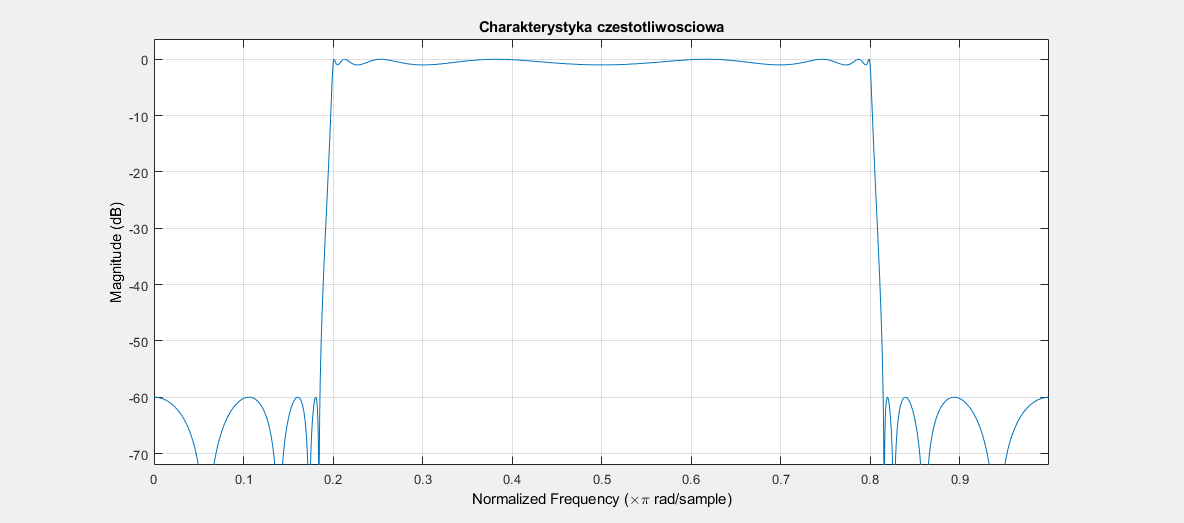


[n, Wn] = ellipord([1000 4000]/5000, [900 4100]/5000,1,60);
[b,a] = ellip(n, 1, 60, Wn);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

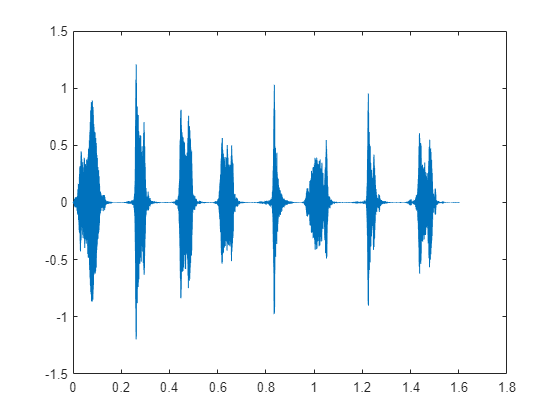


out = filter(b,a,y);
plot(t, out);

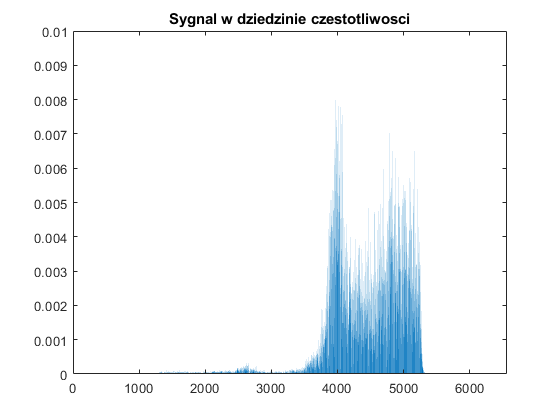

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

### 2.14 Zapoznać się z funkcją `sosfilt()`, filtrowanie drugiego rzędu.

### Przefiltrować sygnał `chirp` filtrem dolnoprzepustowym Butterwortha z zastosowaniem funkcji `butter(),` `sosfilt().`

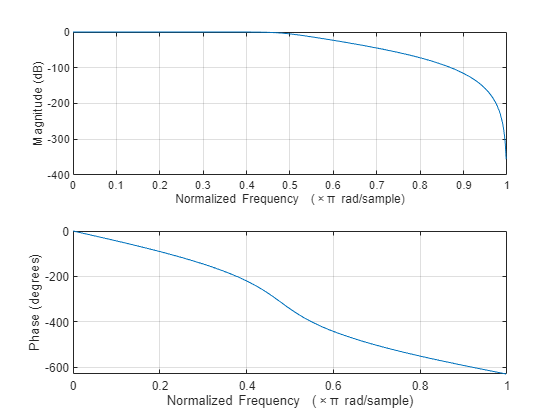

load chirp
[zhi,phi,khi] = butter(7,0.48,'low');
soslo = zp2sos(zhi,phi,khi);
freqz(soslo)


figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

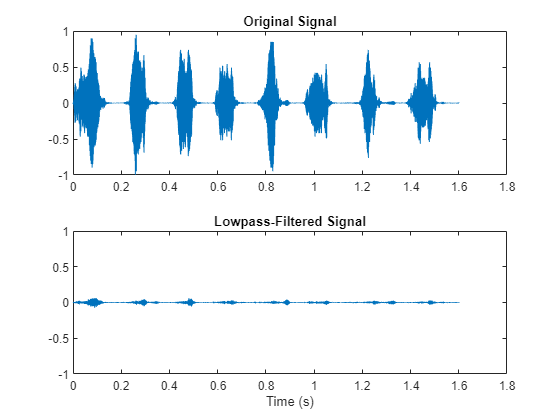


outlo = sosfilt(soslo,y);
subplot(2,1,1)
plot(t,y)
title('Original Signal')
ys = ylim;

subplot(2,1,2)
plot(t,outlo)
title('Lowpass-Filtered Signal')
xlabel('Time (s)')
ylim(ys)

### 2.15 Zapoznać się z funkcją `sosfilt()`. Filtrowanie drugiego rzędu. Przefiltrować sygnał `chirp` filtrem górnoprzepustowym Butterwortha z zastosowaniem funkcji `butter(),` `sosfilt()`. Narysować przebieg częstotliwościowy przefiltrowanego sygnału. Narysować charakterystykę częstotliwościową filtru.

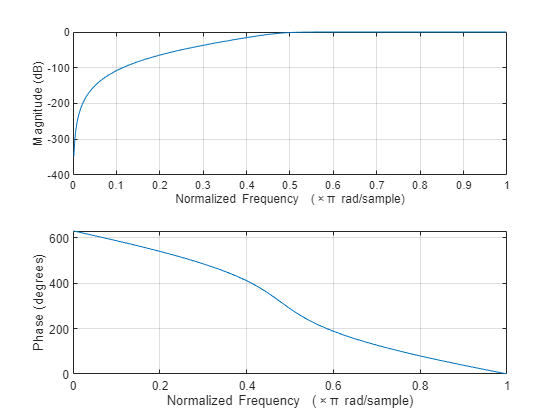

load chirp
[zhi,phi,khi] = butter(7,0.48,'high');
soshi = zp2sos(zhi,phi,khi);
freqz(soshi)


figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

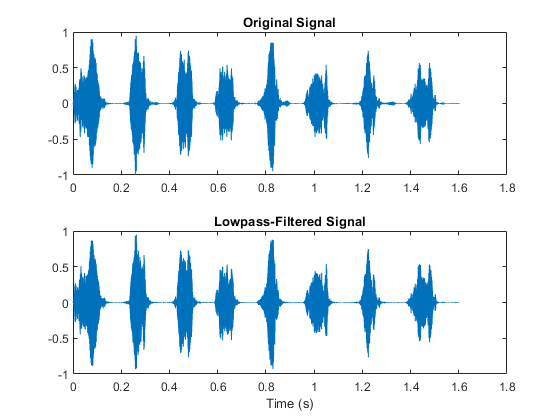


outhi = sosfilt(soshi,y);
subplot(2,1,1)
plot(t,y)a
title('Original Signal')
ys = ylim;

subplot(2,1,2)
plot(t,outhi)
title('Lowpass-Filtered Signal')
xlabel('Time (s)')
ylim(ys)

## 3. Pytania

### 3.1 Informacje na temat w jaki sposób projektujemy filtry IIR.

Filtry IIR sa trudniejsze w projektowaniu od filtrów FIR. Obecnie do projektowania filtru używa sie komputera i odpowiedniego oprogramowania (np Matlab).

### 3.2 Różnice między filtrami FIR i IIR.

Filtry FIR zapewniają nam stabilność, liniowość fazy, sa łatwe w projektowaniu. Sa jednak bardziej obciażajace obliczeniowo. Natomiast filtry IIR charakteryzują się duża szybkśocia działania, kosztem nieliniowosci fazy. Musza byc zaprojektowane tak, aby były stabilne. IIR maja też większą stromość charakterystyki częstotliwościowej w paśmie przejściowym.

### 3.3 Kiedy bardziej wskazane jest użycie filtru FIR a kiedy filtru IIR?

Filtry IIR sprawdzą sie tam, gdzie zależy nam na szybkosci dzialania - sa szybsze od filtrów FIR. Jesli potrzebujemy filtru o dokladnie liniowej fazie - jedynym wyborem sa filtry FIR.

### 3.4 Czy są jakieś różnice w budowie filtrów FIR i IIR.

Filtry FIR nie posiadaja sprzeżenia zwrotnego i korzystają tylko z próbek przeszłych sygnału wejściowego. Filtry IIR korzystają także z przeszłych próbek sygnału wyjściowego - posiadają sprzeżenie zwrotne.